## [Stochastic Gradient Descent](https://apmonitor.com/pds/index.php/Main/StochasticGradientDescent)

Stochastic gradient descent (SGD) is a popular optimization algorithm commonly used in machine learning. It is an iterative algorithm that seeks to find the minimum of a function by taking small steps in the direction of the negative gradient of the function. In other words, at each iteration of the algorithm, the parameters of the function are updated in the direction that reduces the function's value.

Stochastic gradient descent is a simple and very efficient approach to fit linear models. It is particularly useful when the number of samples is very large. It supports different loss functions and penalties for classification. Here is a tutorial that shows how to develop SGD from scratch.

**Advantages:** Efficiency and ease of implementation.

**Disadvantages:** Requires a number of hyper-parameters and it is sensitive to feature scaling.

## **Gradient Descent in MATLAB**

Here is a simple example of gradient descent in MATLAB:

p = [1, 2, 3];

% define the function to be minimized
my_func = @(p) (p(1)-4)^2 + (p(2)-5)^2 + (p(3)-6)^2;

% define the gradient of the function
grad = @(p) [2*(p(1)-4), 2*(p(2)-5), 2*(p(3)-6)];

% set the learning rate
lr = 0.01;

% perform gradient descent for a number of iterations
for i = 1:1000
% calculate the gradient
g = grad(p);

% update the parameters
p(1) = p(1) - lr * g(1);
p(2) = p(2) - lr * g(2);
p(3) = p(3) - lr * g(3);
end

% print the final parameters
disp(p)

    4.0000    5.0000    6.0000



In this example, we define a simple function to be minimized and the gradient, and then use gradient descent to find the minimum of the function by updating the parameters in the direction of the negative gradient. After 1000 iterations, the final values of the parameters is close to the minimum of the function. There is additional information on [**other algorithms such as conjugate gradient, Newton's method, and steepest descent**](https://apmonitor.com/me575/index.php/Main/QuasiNewton) that use gradient (derivative) information to find an optimal solution.

In *stochastic* gradient descent observations are chosen randomly from the training set. This trains on a random subset of the training set between iterations. 

**Optical Character Recognition with SGD in MATLAB**

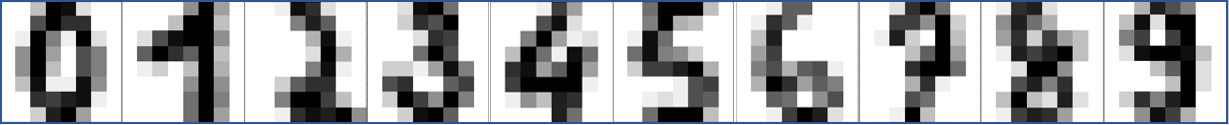

Optical character recognition (OCR) is a method used to convert images of text into machine-readable text. It is typically used to process scanned documents and recognize the text in the images. Stochastic gradient descent (SGD) is a method for training a machine learning model, such as a neural network, by iteratively updating the model's parameters to minimize a loss function. In the context of OCR, SGD can used to train a neural network to recognize characters in images of text.

### Import and Organize Data

% Import dataset of numbers
[XTrain,YTrain] = digitTrain4DArrayData;
[XTest,YTest] = digitTest4DArrayData;

% Split the data 80% training and 20% validation
idx = randperm(size(XTrain,4),1000);
XValidation = XTrain(:,:,:,idx);
XTrain(:,:,:,idx) = [];
YValidation = YTrain(idx);
YTrain(idx) = [];

### Train Neural Network

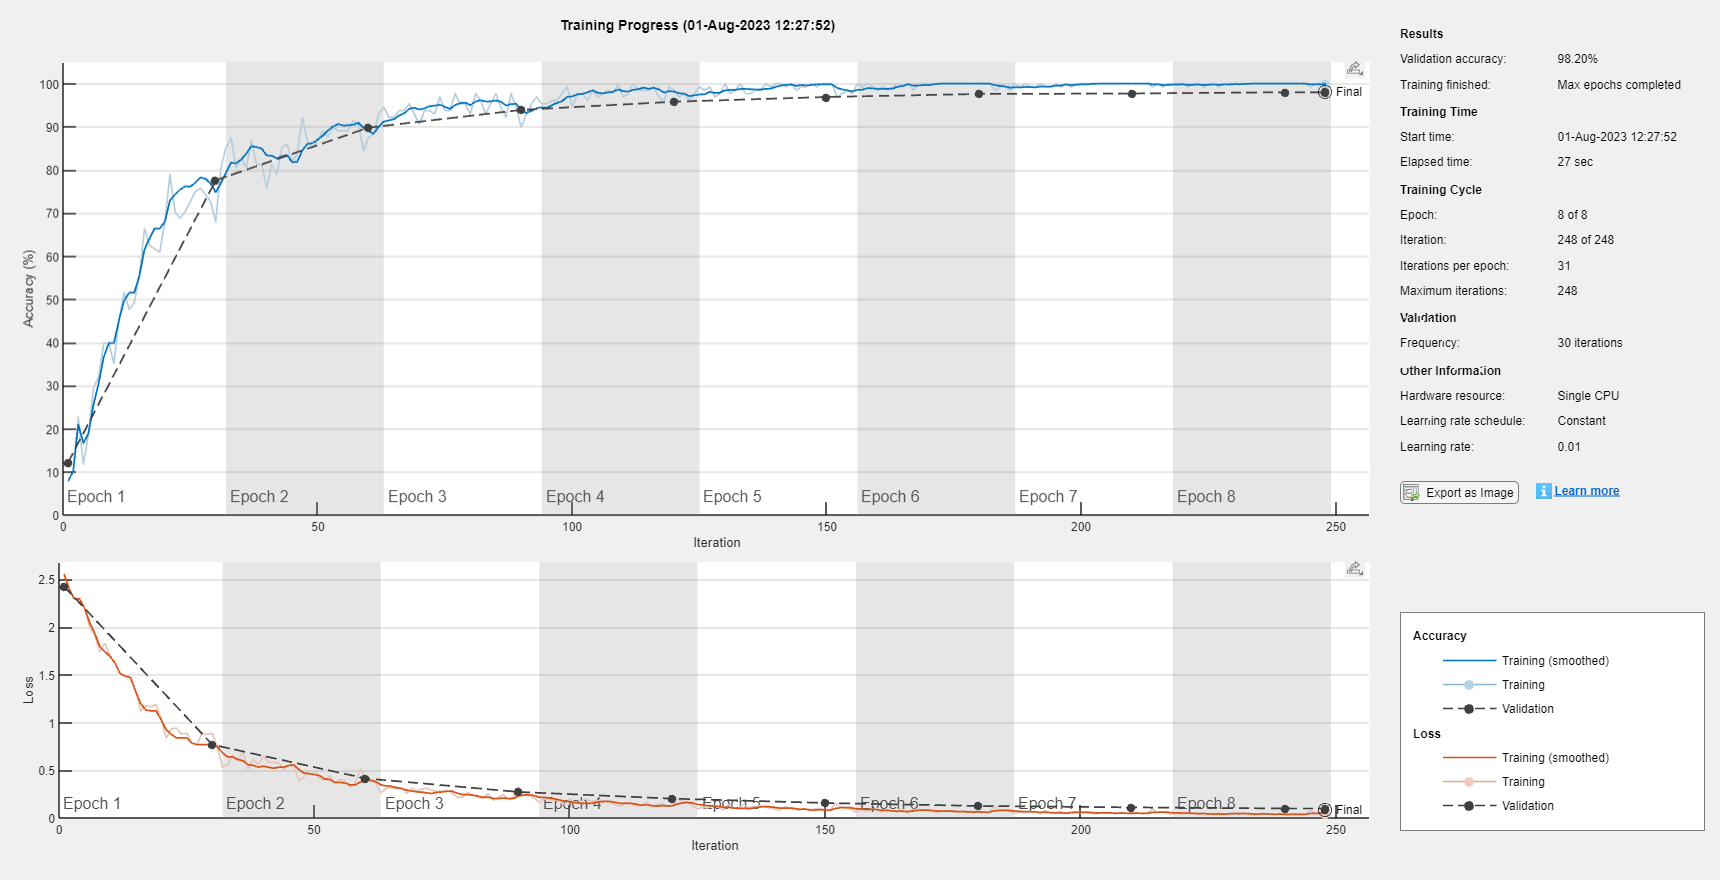

% Construct a network to classify the digit image data
layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer
    reluLayer   
    maxPooling2dLayer(2,Stride=2)
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,Stride=2)
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions("sgdm", ...
    MaxEpochs=8, ...
    ValidationData={XValidation,YValidation}, ...
    ValidationFrequency=30, ...
    Verbose=false, ...
    Plots="training-progress");

% Create fit
net = trainNetwork(XTrain,YTrain,layers,options);

This neural network can also be designed and trained interactively using the [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) app.

### Test Individual Predictions

This is an example that shows a number from the test set and evaluates it with the Stochastic Gradient Descent.

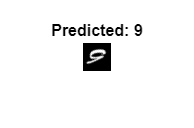

n_samples = length(XTest);

% Select random nummber image
n = randi([0,n_samples],1);

% Predict number based on image
yp = predict(net,XTest(:,:,:,n));
[~,argmax] = max(yp);

% Display the image with the prediction
figure;
imshow(XTest(:,:,:,n));
titleText = "Predicted: " + string(categorical(argmax-1));
title(titleText, 'FontSize', 12)

### Further Reading

See [**trainingOptions**](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) to learn more about the various training options that can be used when training a neural network. 